# ***Wireless Communications***

## ***CA2***

### ***Section 2***

#### ***Reza Jahani - 810198377***

W_channel = 20e6;
Tc = 5e-3;
Td = 10e-6;
Message_length = 1e7;
L = Td * W_channel;
L = round(L);
cp = L - 1;
N_block = 0.5*(Tc * W_channel);
nc = N_block;
N_ofdm = N_block + cp;
Num_OFDM_Blocks = Message_length/N_block;

x = randi([0 1],Message_length,1);
x(x==0) = -1;
x(x==1) = 1;
h = 1/sqrt(2) * (randn(L,1) + 1i*randn(L,1));
H = fft(h,nc);

## ***Q5***

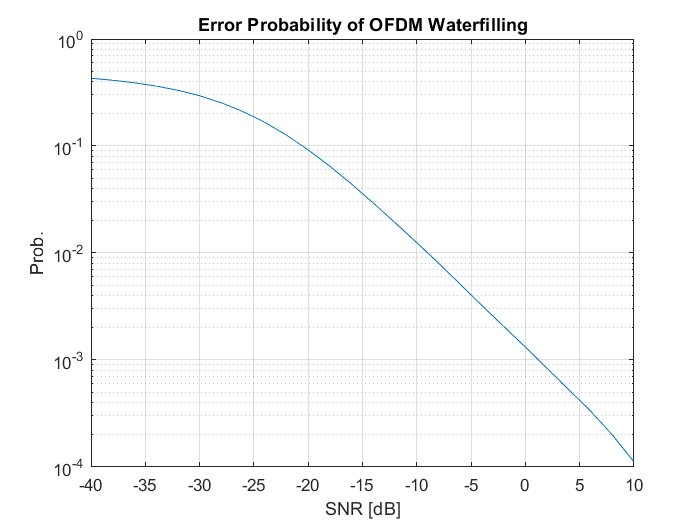

h = 1/sqrt(2) * (randn(L,1) + 1i*randn(L,1));
H = fft(h,nc);
Pi = waterfill(Pmax,abs(H));
theta_H = phase(H);
W_wf = sqrt(Pi);
P = W_wf;
SNR = -40:2:10;
Pmax = 1;
Error_wf = zeros(length(SNR),1);
Channel_Capacity_wf = zeros(length(SNR),1);
for i=1:length(SNR)
    snr = SNR(i);
    snr_lin = 10^(snr/10);
    N0 = Pmax / (snr_lin*nc);
    Y = zeros(Message_length,1);
    C = zeros(Num_OFDM_Blocks,1);
    for block = 1:Num_OFDM_Blocks
            % Transmitter
        block_idx = (block-1)*N_block+1:block*N_block;
        x_t = x(block_idx);
        x_t = x_t .* W_wf .* exp(-1i*theta_H);
        X_t = ifft(x_t);
        CP = X_t(end-cp+1:end);
        X_cp = [CP;X_t];
            % Channel
        r = conv(X_cp,h);
            % Receiver
        r = r(cp+1:nc+cp);
        n = sqrt(N0/2) * (randn(N_block,1)+1i*randn(N_block,1));
        r = r + n;
        y = fft(r);
        Y(block_idx) = y;
        
            % Channel Capacity
        C_temp = log(Pi.*(abs(H).^2)/N0 + 1);
        C_temp = sum(C_temp);
        C(block) = C_temp;
    end
    Channel_Capacity_wf(i) = mean(C);
    Y(Y>=0) = 1;
    Y(Y<0) = -1;
    correct_estimation = sum(Y==x);
    Pe = 1 - correct_estimation/Message_length;
    Error_wf(i) = Pe;
end
figure(3);
semilogy(SNR,Error_wf);
xlabel('SNR [dB]');
ylabel('Prob.');
title('Error Probability of OFDM Waterfilling');
grid on;

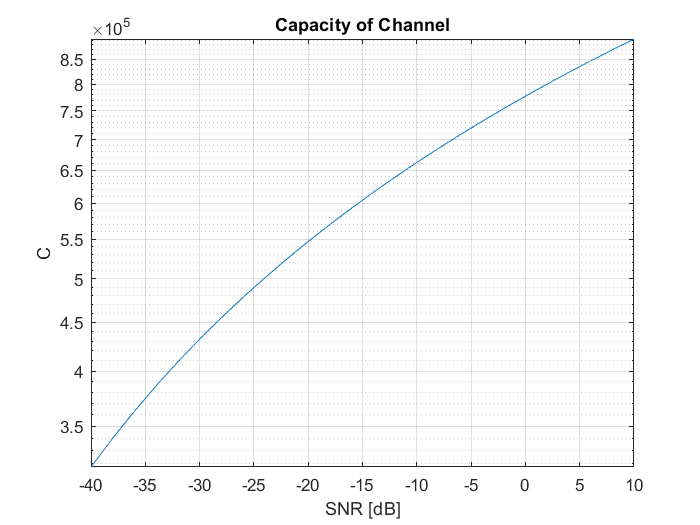

figure(4);
semilogy(SNR,abs(Channel_Capacity_wf));
xlabel('SNR [dB]');
ylabel('C');
title('Capacity of Channel');
grid on;

## ***Q6***

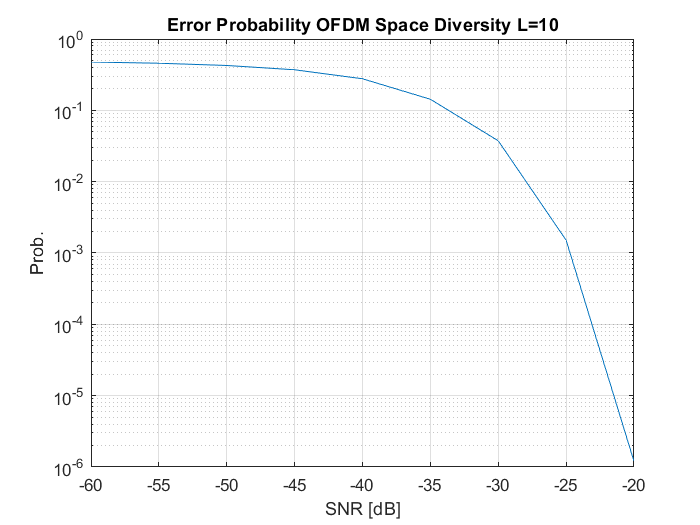

SNR = -60:5:20;
Pmax = 1;
Error_sd = zeros(length(SNR),1);
M = 10;
for i=1:length(SNR)
    snr = SNR(i);
    snr_lin = 10^(snr/10);
    N0 = Pmax / (snr_lin*nc);
    Y = zeros(Message_length,1);
    h = 1/sqrt(2)*(randn(L,M)+1i*randn(L,M));
    H = fft(h,nc);
    for block=1:Num_OFDM_Blocks
            % Transmitter
        block_idx = (block-1)*N_block+1:block*N_block;
        x_t = x(block_idx);
        X_t = ifft(x_t);
        CP = X_t(end-cp+1:end);
        X_cp = [CP;X_t];
            % Channel
        theta_H = zeros(N_block,M);
        R = zeros(nc,M);
        for l=1:M
            r = conv(X_cp,h(:,l));
            R(:,l) = r(cp+1:nc+cp);
            theta_H(:,l) = phase(H(:,l));
        end
            % Receiver
        n = sqrt(N0/2) * (randn(N_block,M)+1i*randn(N_block,M));
        R = R + n;
        Z = fft(R);
            % MRC
        Z = exp(-1i*theta_H) .* Z;
        Z = abs(H).^2/N0 .* Z;
        Z = sum(Z,2);
        Y(block_idx) = Z;
     end
        Y(Y>=0) = 1;
        Y(Y<0) = -1;
        correct_estimation = sum(Y==x);
        Pe = 1 - correct_estimation/Message_length;
        Error_sd(i) = Pe;
end
figure(5);
semilogy(SNR,Error_sd);
xlabel('SNR [dB]');
ylabel('Prob.');
title('Error Probability OFDM Space Diversity L=10');
grid on;

## ***Q7***

***Zero Forcing***

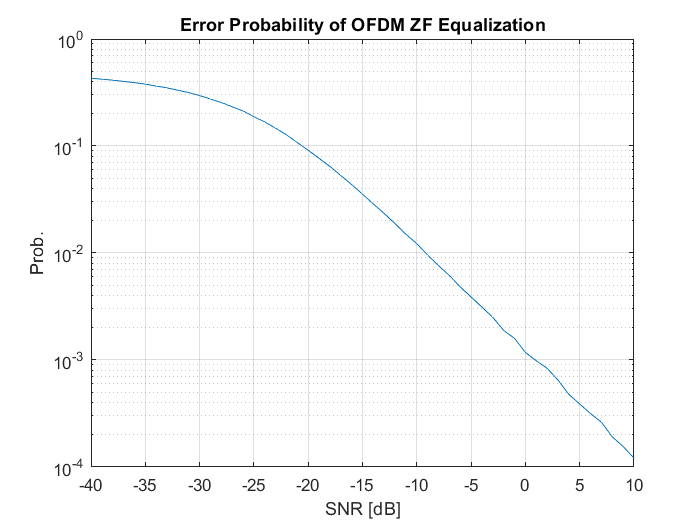

SNR = -40:10;
Pmax = 1;
Error_zf = zeros(length(SNR),1);
for i=1:length(SNR)
    snr = SNR(i);
    snr_lin = 10^(snr/10);
    N0 = Pmax / (snr_lin*nc);
    Y = zeros(Message_length,1);
    for block = 1:Num_OFDM_Blocks
        h = 1/sqrt(2) * (randn(L,1) + 1i*randn(L,1));
        H = fft(h,nc);
        W_zf = 1./H;
            % Transmitter
        block_idx = (block-1)*N_block+1:block*N_block;
        x_t = x(block_idx);
        X_t = ifft(x_t,nc);
        CP = X_t(end-cp+1:end);
        X_cp = [CP;X_t];
            % Channel
        r = conv(h,X_cp);
            % Receiver
        r = r(cp+1:nc+cp);
        n = sqrt(N0/2) * (randn(N_block,1)+1i*randn(N_block,1));
        r = r + n;
        y = fft(r,nc);
        y = y .* W_zf;
        Y(block_idx) = y;
    end
    Y(real(Y)>=0) = 1;
    Y(real(Y)<0) = -1;
    correct_estimation = sum(Y==x);
    Pe = 1 - correct_estimation/Message_length;
    Error_zf(i) = Pe;
end
figure(6);
semilogy(SNR,Error_zf);
xlabel('SNR [dB]');
ylabel('Prob.');
title('Error Probability of OFDM ZF Equalization');
grid on;

***MMSE***

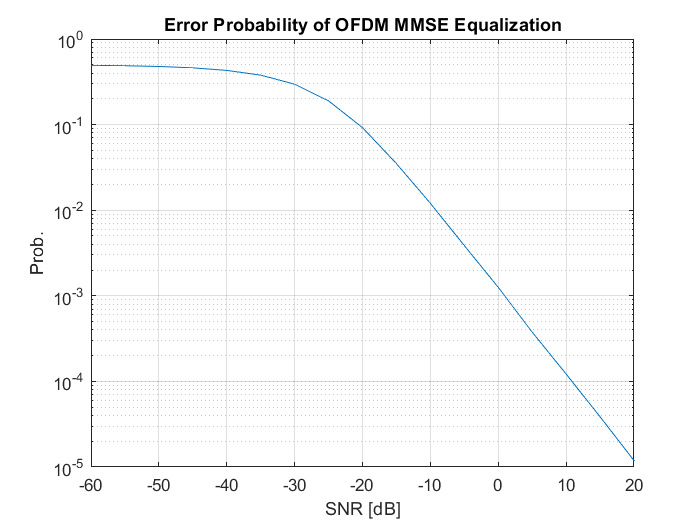

SNR = -60:5:20;
Pmax = 1;
Error_mmse = zeros(length(SNR),1);
for i=1:length(SNR)
    snr = SNR(i);
    snr_lin = 10^(snr/10);
    N0 = Pmax / (snr_lin*nc);
    Y = zeros(Message_length,1);
    for block = 1:Num_OFDM_Blocks
        h = 1/sqrt(2) * (randn(L,1) + 1i*randn(L,1));
        H = fft(h,nc);
        W_mmse = conj(H)./(abs(H).^2 + N0);
            % Transmitter
        block_idx = (block-1)*N_block+1:block*N_block;
        x_t = x(block_idx);
        X_t = ifft(x_t);
        CP = X_t(end-cp+1:end);
        X_cp = [CP;X_t];
            % Channel
        r = conv(h,X_cp);
            % Receiver
        r = r(cp+1:nc+cp);
        n = sqrt(N0/2) * (randn(N_block,1)+1i*randn(N_block,1));
        r = r + n;
        y = fft(r);
        y = y .* W_mmse;
        Y(block_idx) = y;
    end
    Y(Y>=0) = 1;
    Y(Y<0) = -1;
    correct_estimation = sum(Y==x);
    Pe = 1 - correct_estimation/Message_length;
    Error_mmse(i) = Pe;
end
figure(7);
semilogy(SNR,Error_mmse);
xlabel('SNR [dB]');
ylabel('Prob.');
title('Error Probability of OFDM MMSE Equalization');
grid on;

## ***Q8***

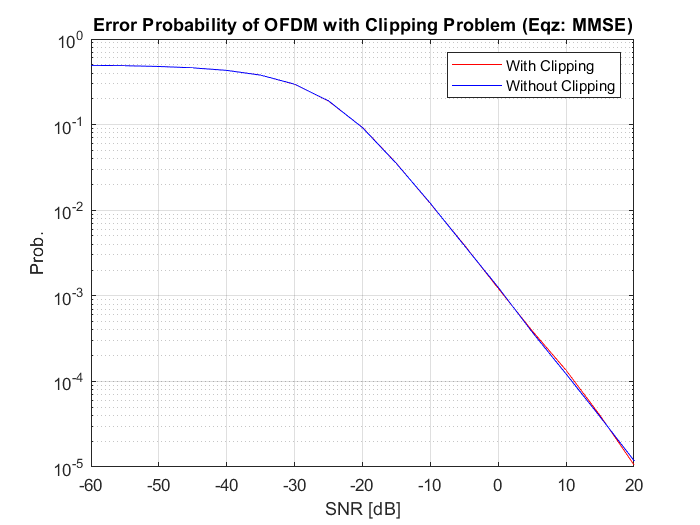

SNR = -60:5:20;
Pmax = 1;
Error_clip = zeros(length(SNR),1);
for i=1:length(SNR)
    snr = SNR(i);
    snr_lin = 10^(snr/10);
    N0 = Pmax / (snr_lin*nc);
    Y = zeros(Message_length,1);
    for block = 1:Num_OFDM_Blocks
        h = 1/sqrt(2) * (randn(L,1) + 1i*randn(L,1));
        H = fft(h,nc);
        W_mmse = conj(H)./(abs(H).^2 + N0);
            % Transmitter
        block_idx = (block-1)*N_block+1:block*N_block;
        x_t = x(block_idx);
        X_t = ifft(x_t);
                % Clipping
        X_t(X_t>=0.8*max(abs(X_t))) = 0.8/sqrt(2) * max(X_t);
        CP = X_t(end-cp+1:end);
        X_cp = [CP;X_t];
            % Channel
        r = conv(h,X_cp);
            % Receiver
        r = r(cp+1:nc+cp);
        n = sqrt(N0/2) * (randn(N_block,1)+1i*randn(N_block,1));
        r = r + n;
        y = fft(r);
        y = y .* W_mmse;
        Y(block_idx) = y;
    end
    Y(Y>=0) = 1;
    Y(Y<0) = -1;
    correct_estimation = sum(Y==x);
    Pe = 1 - correct_estimation/Message_length;
    Error_clip(i) = Pe;
end
figure(7);
semilogy(SNR,Error_clip,'r'); hold on;
semilogy(SNR,Error_mmse,'b'); hold off;
legend('With Clipping','Without Clipping');
xlabel('SNR [dB]');
ylabel('Prob.');
title('Error Probability of OFDM with Clipping Problem (Eqz: MMSE)');
grid on;